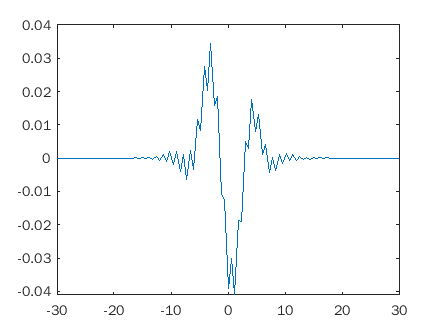

a=-30;
b=30;
x0=0.1;
sigma=1;
T=5; 
m=100;
h=1/(m+1);
N=50;
k=T/N;

funinit=@(x) exp(-x.^2);
x=linspace(a,b,m+1);
Us=zeros([m+1, N]);
Us(:,1)=funinit(x);

figure
pplot=plot(x,Us(:,1));
hold on
for i=1:N
    Un=Us(:,i);
    Unp=backeustep(Un,k,h,m+1);
    Us(:,i+1)=Unp;
    [pplot.YData] = deal(Unp);
    pause(0.5)
end

function Unp1=backeustep(Un,k,h,m)
% One step of Backward Euler's method.
%
%                       Input arguments:
%
%  Un - array of u.
%  k - time step.
%  h - grid size.
%  m - total number of grid.
%
%                       Output arguments:
%
%  Unp1 - a vector of length m+1; solution of pde.
    e=ones(m,1);

    Tx=spdiags([e 0*e -e],-1:1,m,m);
    Tx(1,end)=1;
    Tx(end,1)=-1;

    Txx=spdiags([e -2*e e],-1:1,m,m);
    Txx(1,end)=1;
    Txx(end,1)=1;

    Txxxx=spdiags([e -4*e 6*e -4*e e],-2:2,m,m);
    Txxxx(1,end)=-4;
    Txxxx(end,1)=-4;
    Txxxx(2,end)=1;
    Txxxx(1,end-1)=1;
    Txxxx(end,2)=1;
    Txxxx(end-1,1)=1;

    Ux=Tx*Un/(2*h);

    T1=spdiags((Un.*Ux),0,m,m);
%     T1=speye(m)*norm(Ux)^2/2;
    T2=Txx*Un/(h^2);
    T3=Txxxx*Un/h^4;

    A=speye(m)+k*(T1+T2+T3);

    Unp1=A\Un;

end